Nom:    Adrian Cristian Crisan

Link:    [https://drive.matlab.com/sharing/c756aebc-d50b-4e26-9870-92c1306a466f](https://drive.matlab.com/sharing/c756aebc-d50b-4e26-9870-92c1306a466f)

### 1. Braitenberg vehicles (page 127) 

#### a) Experiment with different starting configurations and control gains.

To change [x, y, theta] you just have to double click the Bycicle block and change the parameters, his modifications can bee seen in sl_braitenberg_experiment.slx.

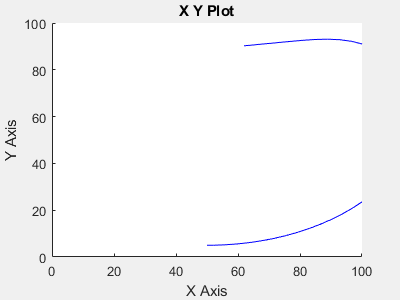

clear
close all
clf

sim('sl_braitenberg_experiment');

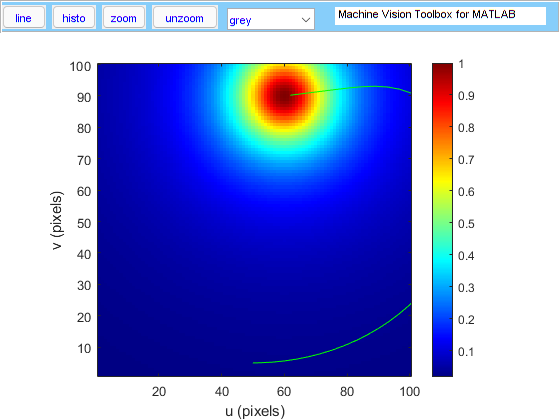

[X, Y] = meshgrid(1:100, 1:100);
field = sensorfield(X, Y);
idisp(field, 'ynormal', 'colormap', 'jet', 'bar')
hold on
plot(xout(:, 1), xout(:, 2), 'g')

#### b) Modify the signs on the steering signal to make the vehicle light-phobic.

I just change the steering gain to a negative number, this modifications can bee seen in sl_braitenberg_light_phobic.slx.

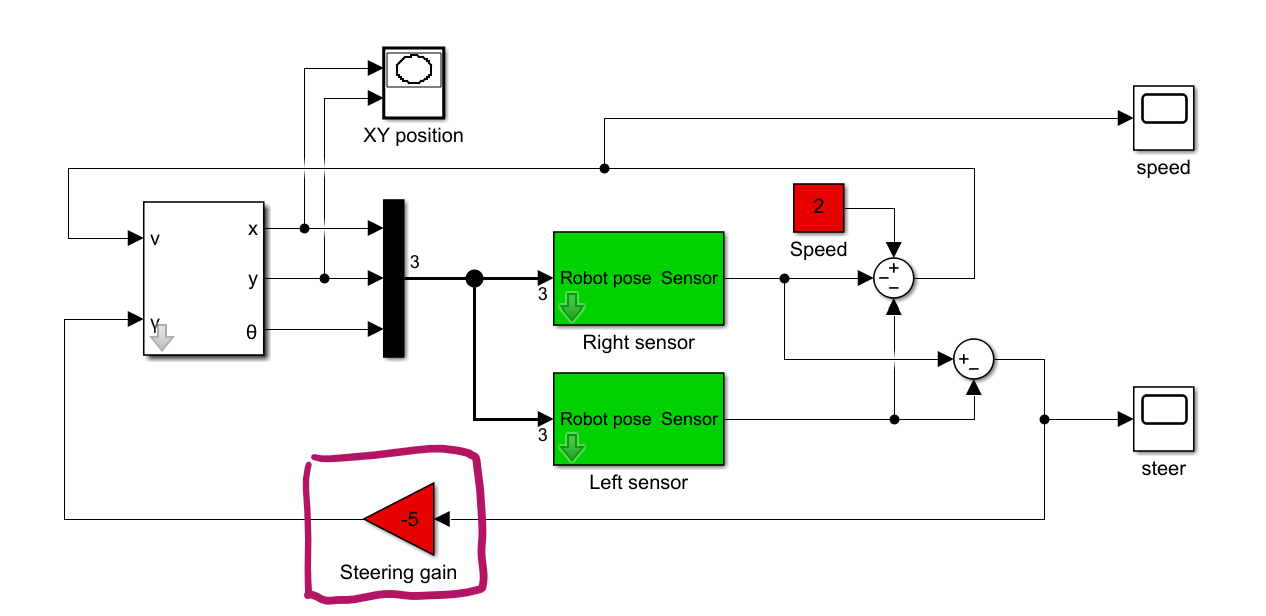

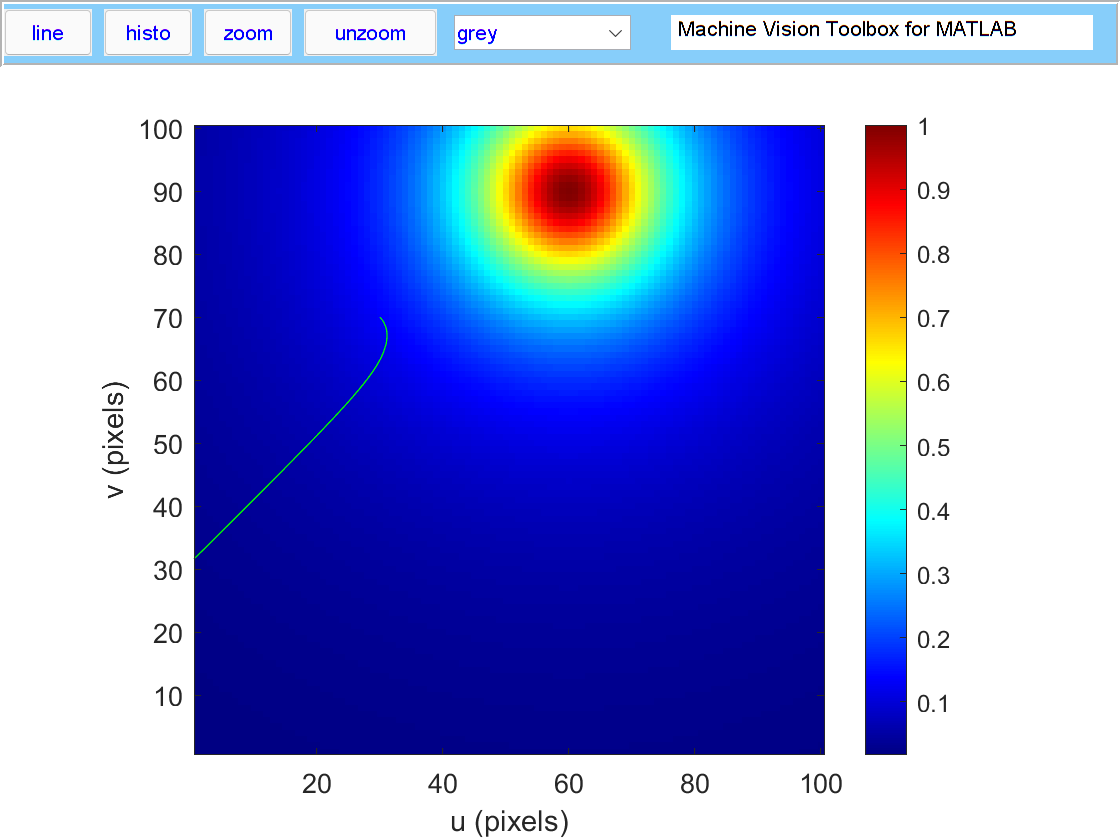

clear
close all
clf

sl_braitenberg_light_phobic

sim('sl_braitenberg_light_phobic');
[X, Y] = meshgrid(1:100, 1:100);
field = sensorfield(X, Y);
idisp(field, 'ynormal', 'colormap', 'jet', 'bar')
hold on
plot(xout(:, 1), xout(:, 2), 'g')

#### c) Modify the sensorfield function so that the peak moves with time.

I modified the sensor function to carry out this task (sensorfield2.m) and the sensors block of sl_braitenberg, adding a clock and changing the number of parameters that we pass. this modifications can bee seen in sl_braitenberg_peak_time.slx.

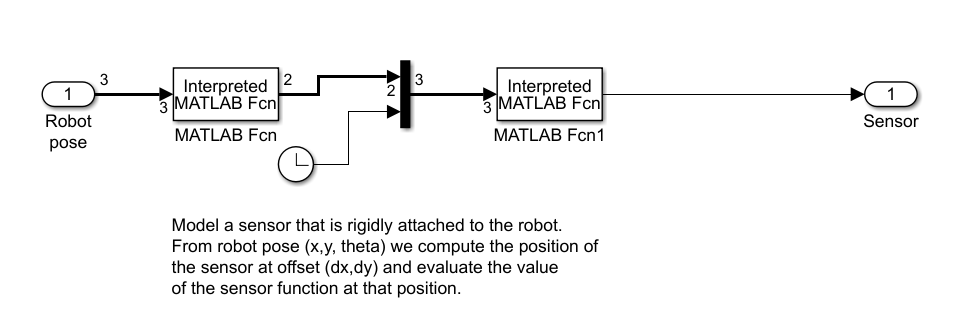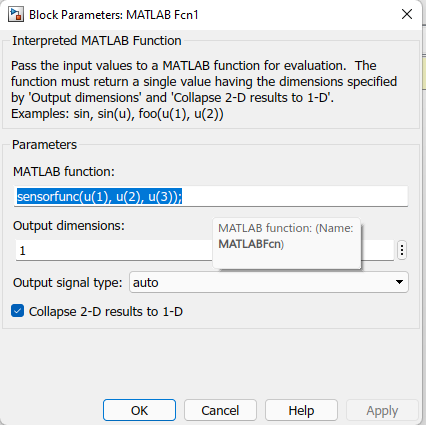

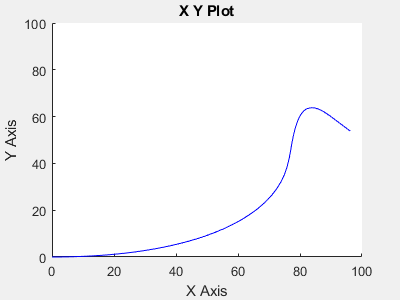

clear
close all
clf

sim('sl_braitenberg_peak_time');

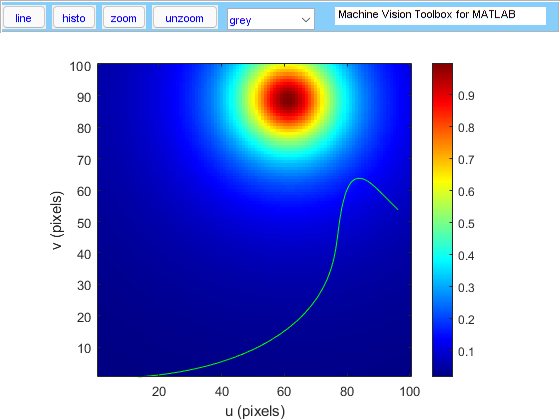

[X, Y] = meshgrid(1:100, 1:100);
time = 0:0.1:99*0.1;
field = sensorfield2(X, Y, time);
idisp(field, 'ynormal', 'colormap', 'jet', 'bar')
hold on
plot(xout(:, 1), xout(:, 2), 'g')

#### d) The vehicle approaches the maxima asymptotically. Add a stopping rule so that  the vehicle stops when the when either sensor detects a value greater than 0.95. 

The modifiecation I did to sl_breitenberg, this modifications can bee seen in sl_braitenberg_stop_rule.slx.

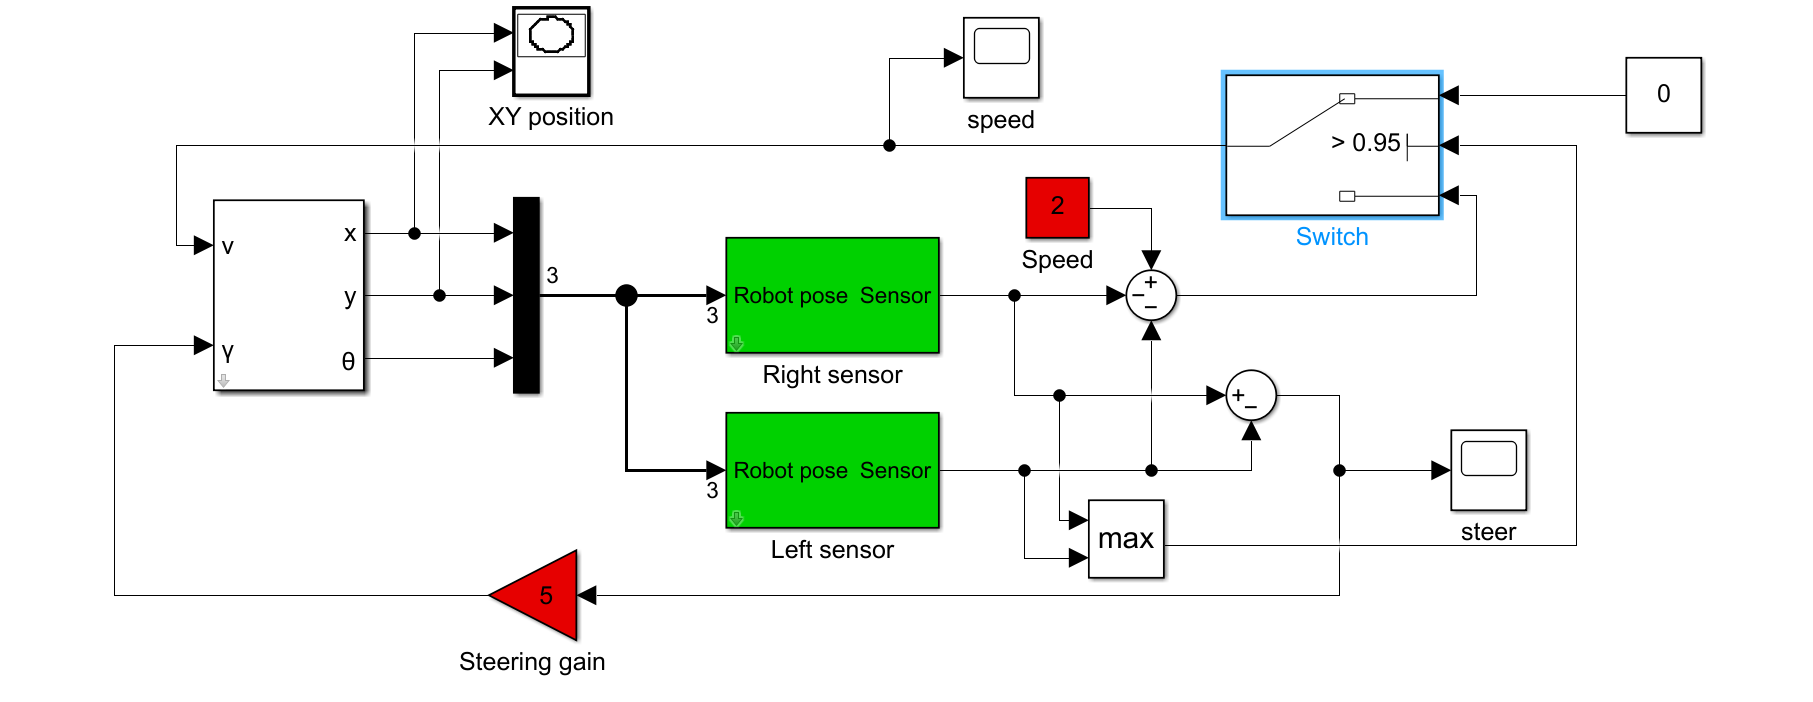

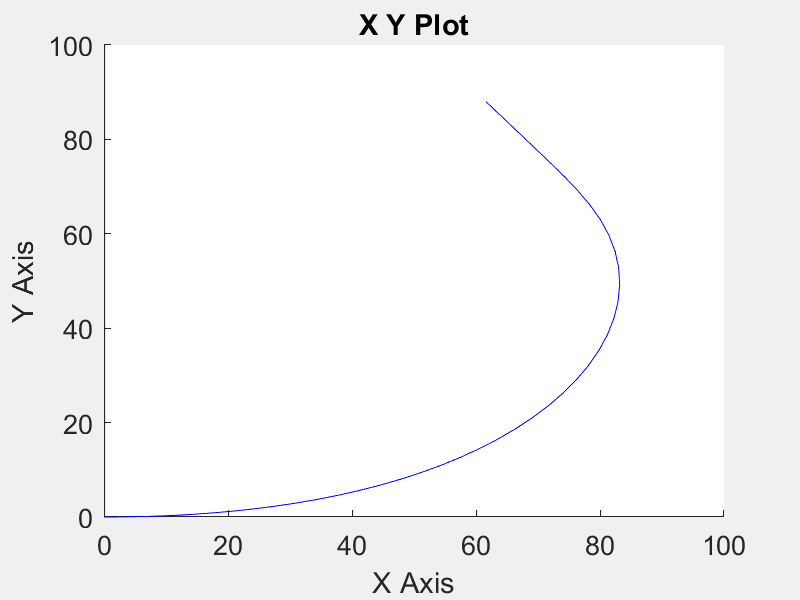

clear
close all
clf

sim('sl_braitenberg_stop_rule');

[X, Y] = meshgrid(1:100, 1:100);
field = sensorfield(X, Y);
idisp(field, 'ynormal', 'colormap', 'jet', 'bar')
hold on
plot(xout(:, 1), xout(:, 2), 'g')

#### e) Create a scalar field with two peaks. Can you create a starting pose where the  robot gets confused?

I modified the function sensorfield, the modifications can bee seen in sensorfield3.m. I modified also the callings to the functions of the sensors to sensorfield3, this modifications can bee seen in sl_braitenberg_two_peaks.slx.

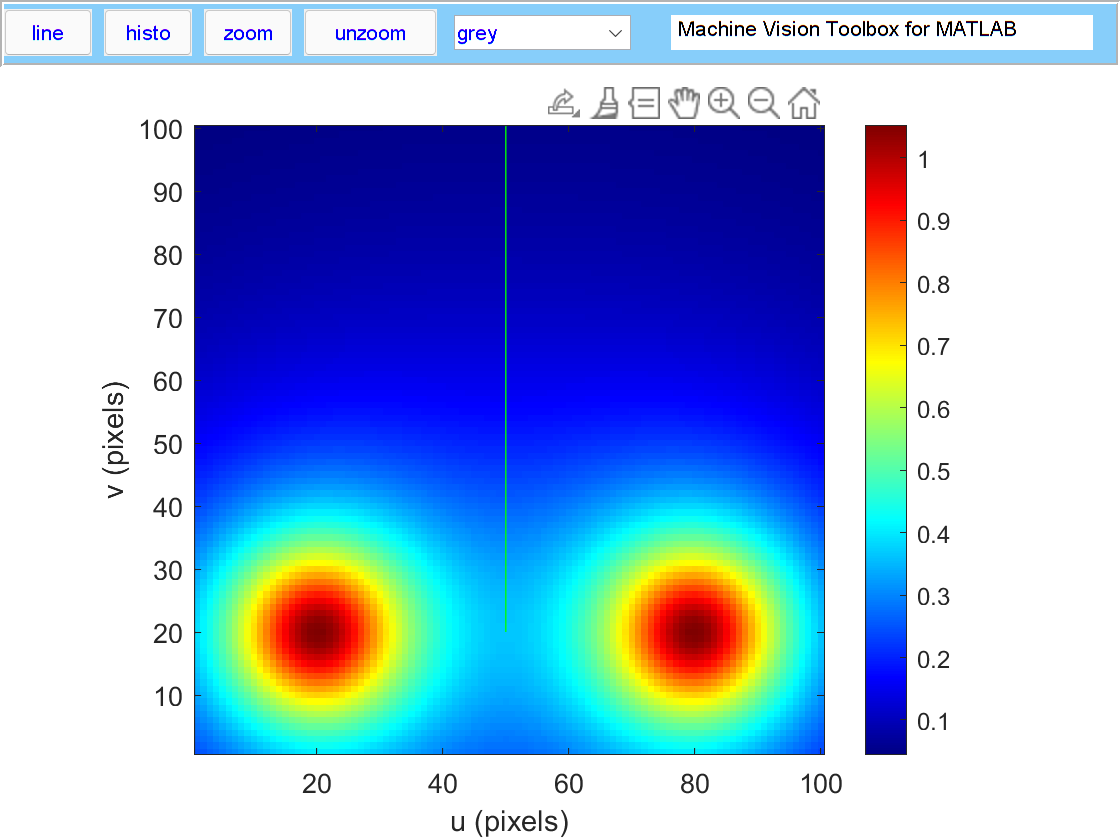

clear
close all
clf

sim('sl_braitenberg_two_peaks');
[X, Y] = meshgrid(1:100, 1:100);
field = sensorfield3(X, Y);
idisp(field, 'ynormal', 'colormap', 'jet', 'bar')
hold on
plot(xout(:, 1), xout(:, 2), 'g')

### 3. Bug algorithms (page 128) 

#### a) Using the function makemap create a new map to challenge bug2. Try different  starting points. 

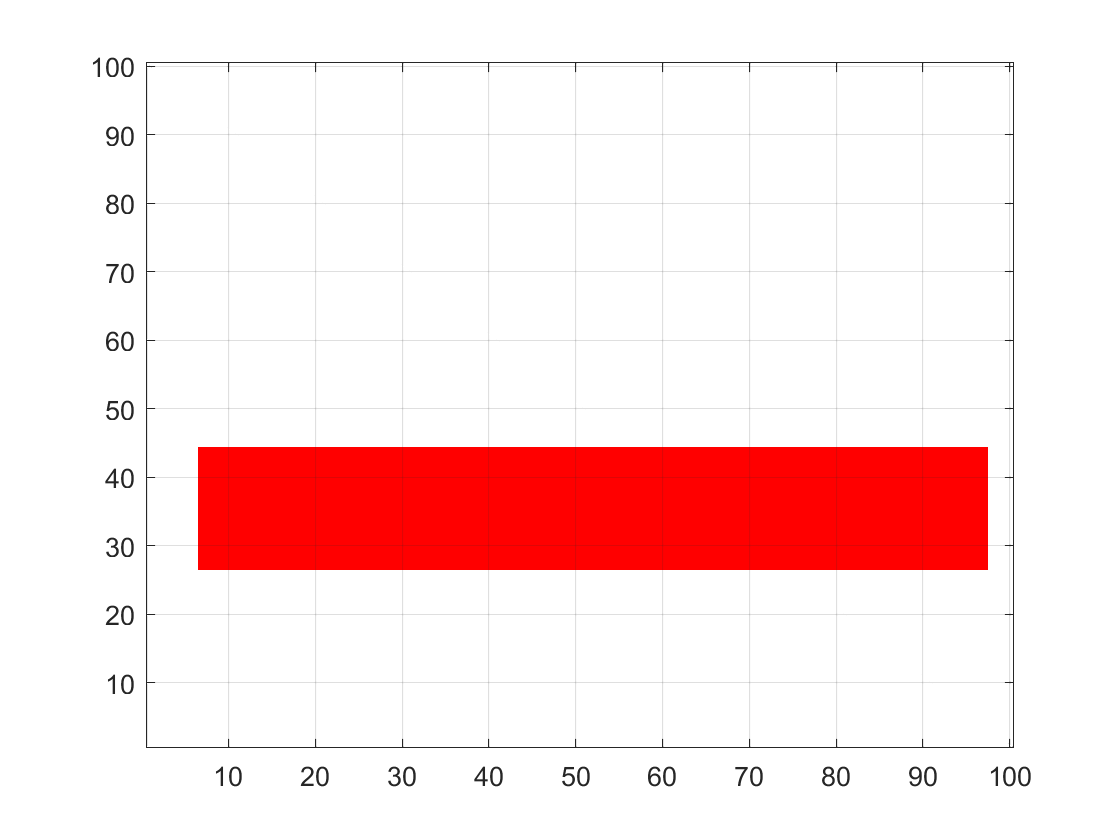

makemap:
  left button, click and drag to create a rectangle
  or type the following letters in the figure window:
  p - draw polygon
  c - draw circle
  e - erase map
  u - undo last action
  q - leave editing mode


point1 =     7.4700   43.6387


point2 =    97.2166   26.9964


clear
close all
clf

map = makemap(100);

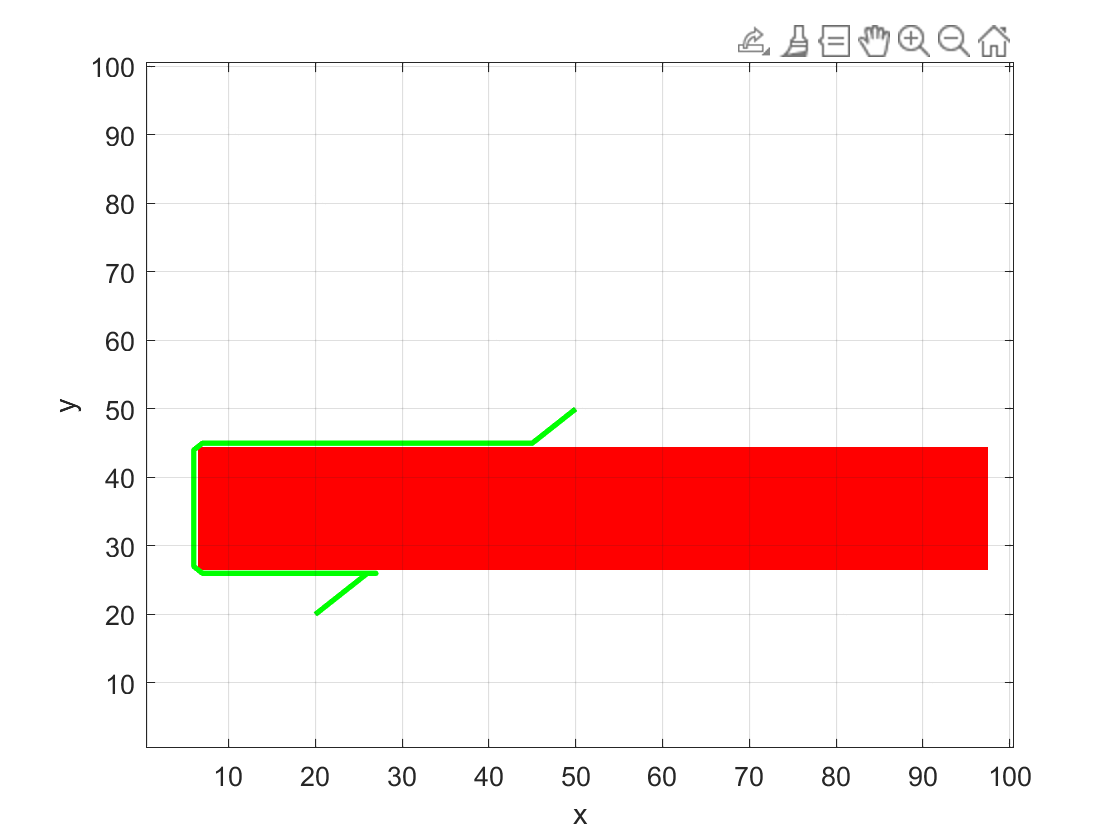

bug = Bug2(map);
bug.plot();
p = bug.query([50, 50], [20 20]);
hold on
plot(p(:, 1), p(:, 2), 'g', 'LineWidth',2)

#### b) Create an obstacle map that contains a maze. Can bug2 solve the maze? 

As we can see en the following figure, Bug2 can solve the maze.

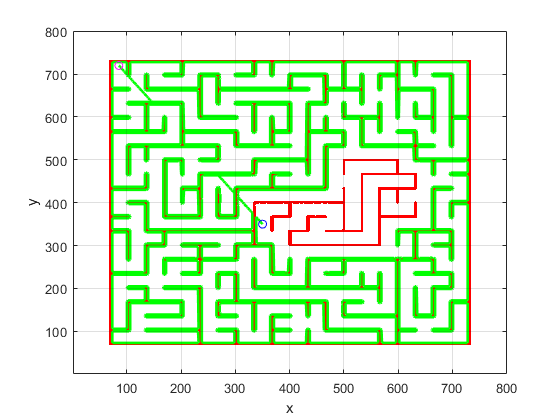

clear
close all
clf

% Read the maze
map = imread('maze.jpg');  
% Binarize the image
map = rgb2gray(map);
% Establish the walls
map = int8(map < 100);
% Remove the exits/entring of the maze
map(68:72, 68:733) = 1;
map(68:733, 68:72) = 1;

bug = Bug2(map);
bug.plot();
hold on
start = [85, 720];
goal = [350, 350];
p = bug.query(start, goal);
plot(p(:, 1), p(:, 2), 'g', 'LineWidth',2)
scatter(start(1), start(2), 'm');
scatter(goal(1), goal(2), 'b');

#### c) Experiment with different start and goal locations.

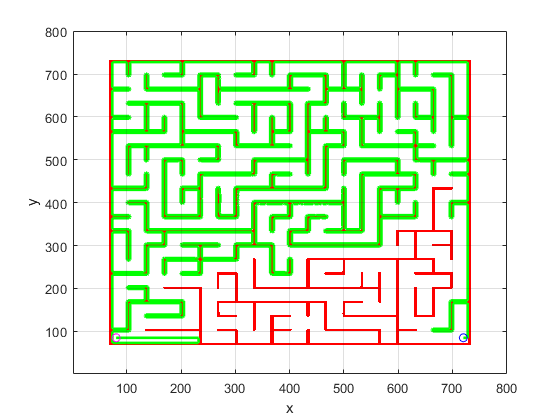

bug = Bug2(map);
bug.plot();
hold on
start = [80, 85];
goal = [720, 85];
p = bug.query(start, goal);
plot(p(:, 1), p(:, 2), 'g', 'LineWidth',2)
scatter(start(1), start(2), 'm');
scatter(goal(1), goal(2), 'b');

#### d) Create a bug trap. Make a hollow box, and start the bug inside a box with the goal outside. What happens? 

The execution throw us an error confirming that could not reach the goal.

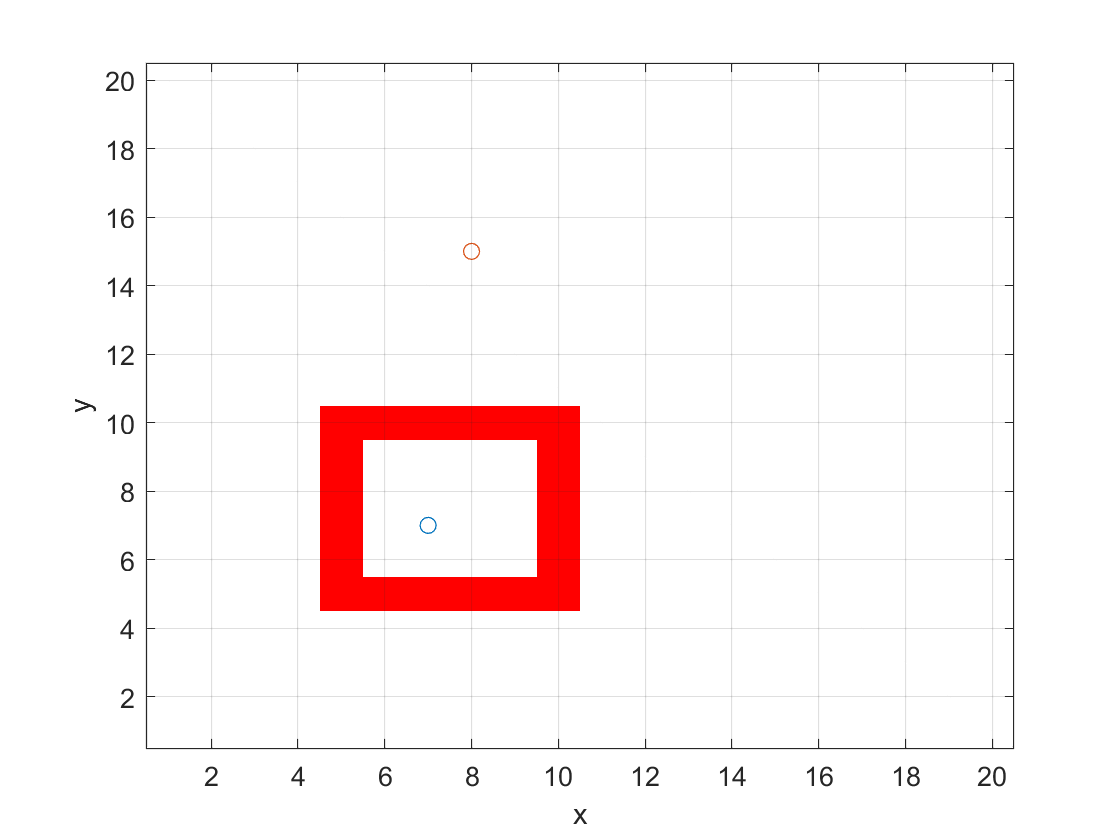

clear
close all
clf

map = zeros(20);
map(5:10, 5) = 1;
map(5:10, 10) = 1;
map(5, 5:10) = 1;
map(10, 5:10) = 1;
bug = Bug2(map);
bug.plot();
hold on
start = [7, 7];
goal = [8, 15];
scatter(start(1), start(2))
scatter(goal(1), goal(2))

p = bug.query(start, goal);

Error using Navigation/checkquery
Too many output arguments.

#### e) Modify bug2 to change the direction it turns when it hits an obstacle.

I created a new Bug2 file and added into this the following propertie and method:

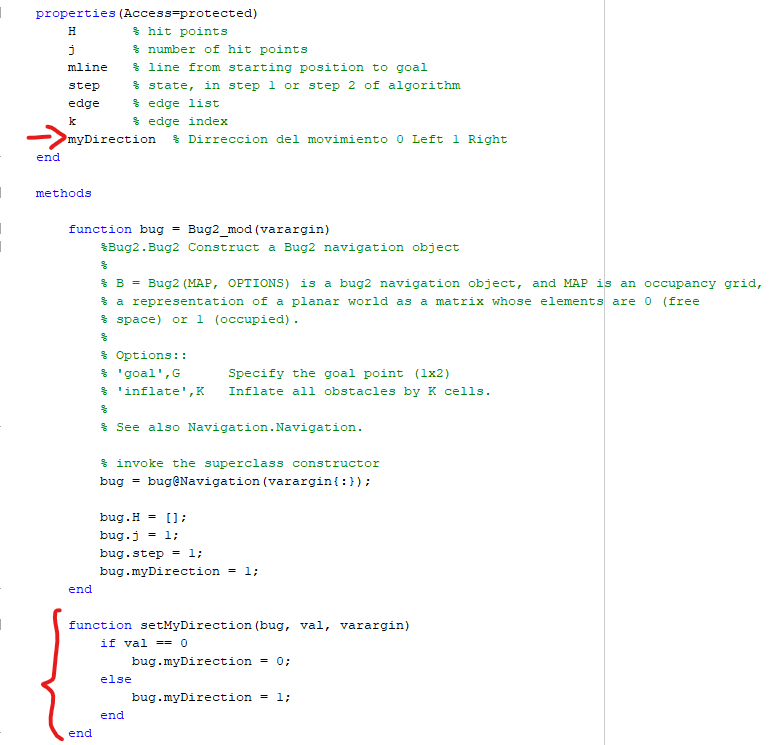

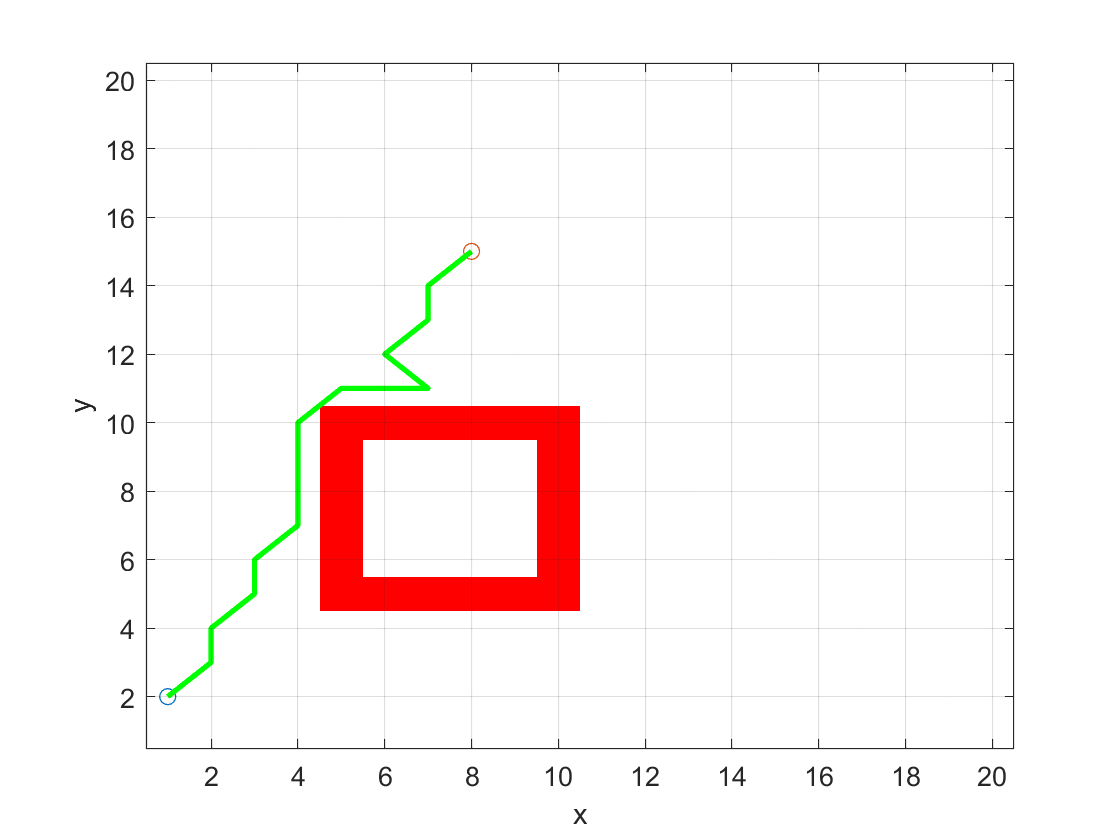

clear
close all
clf

map = zeros(20);
map(5:10, 5) = 1;
map(5:10, 10) = 1;
map(5, 5:10) = 1;
map(10, 5:10) = 1;
bug = Bug2_mod(map);
bug.plot();
hold on
start = [1, 2];
goal = [8, 15];
scatter(start(1), start(2))
scatter(goal(1), goal(2))
bug.setMyDirection(1);                  % Change to 0 to return the previous direction when finds an obstacle
p = bug.query(start, goal);
plot(p(:, 1), p(:, 2), 'g', 'LineWidth', 2)
hold off

The  original way that the bug takes when hits an obstacle.

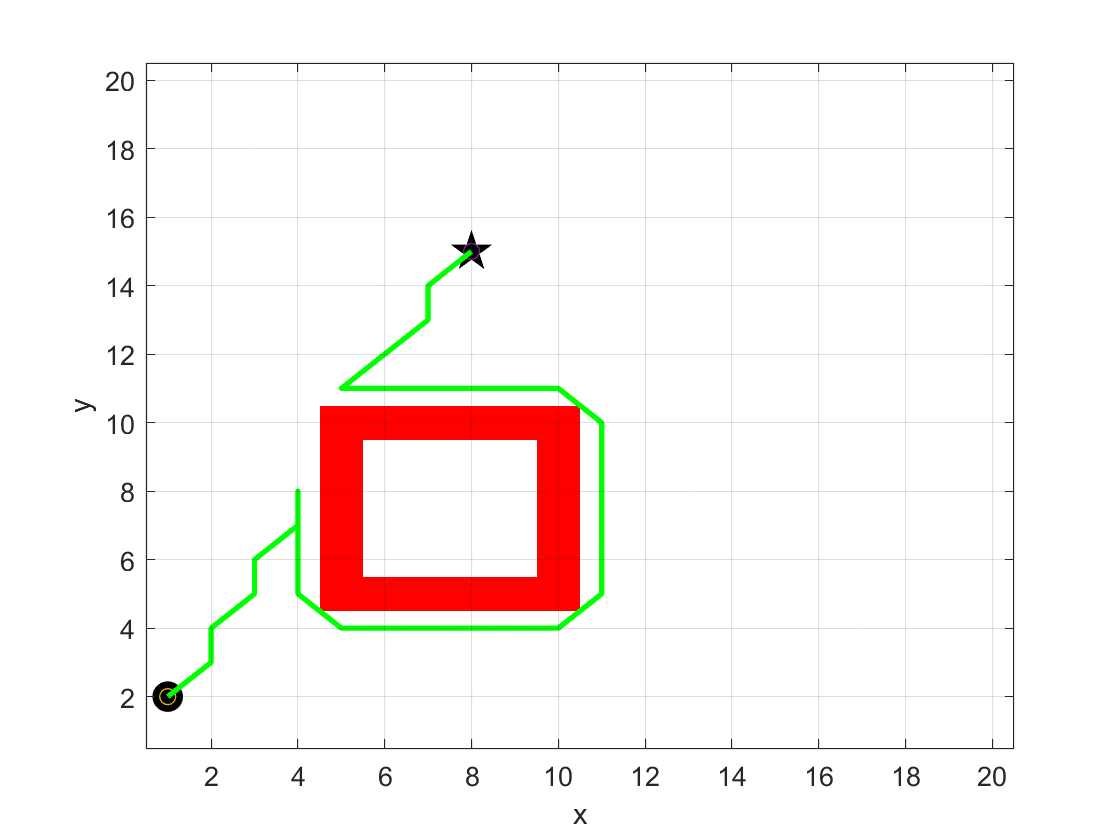

bug.plot();
hold on
start = [1, 2];
goal = [8, 15];
scatter(start(1), start(2))
scatter(goal(1), goal(2))
bug.setMyDirection(0);                  % Change to 0 to return the previous direction when finds an obstacle
p = bug.query(start, goal);
plot(p(:, 1), p(:, 2), 'g', 'LineWidth', 2)